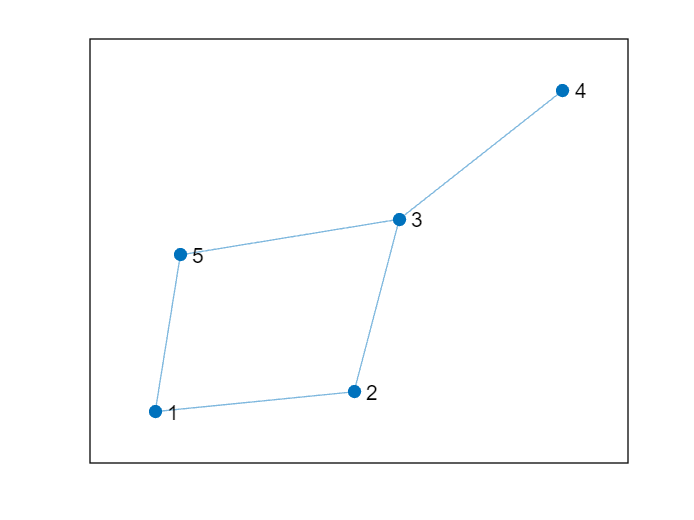

clear, clc, clf

A = [
    0, 1, 0, 0, 1;
    1, 0, 1, 0, 0;
    0, 1, 0, 1, 1;
    0, 0, 1, 0, 0;
    1, 0, 1, 0, 0;
];

G = graph(A);
figure
plot(G)

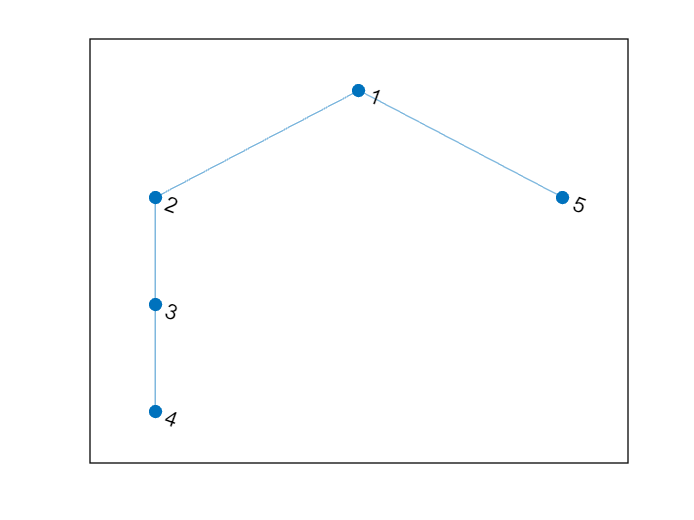

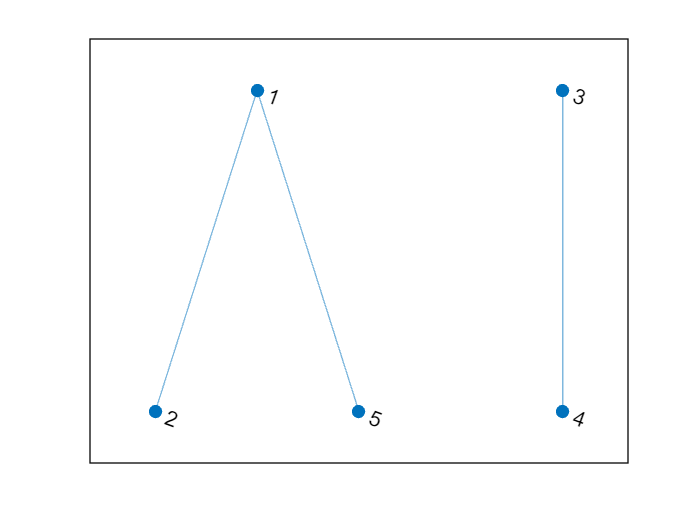

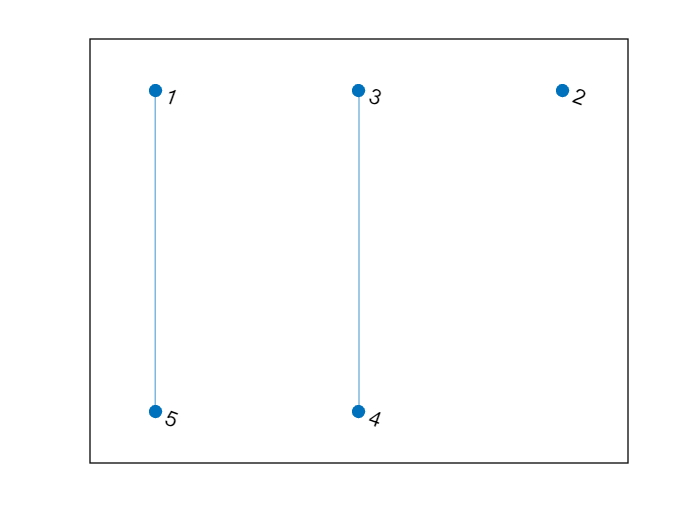

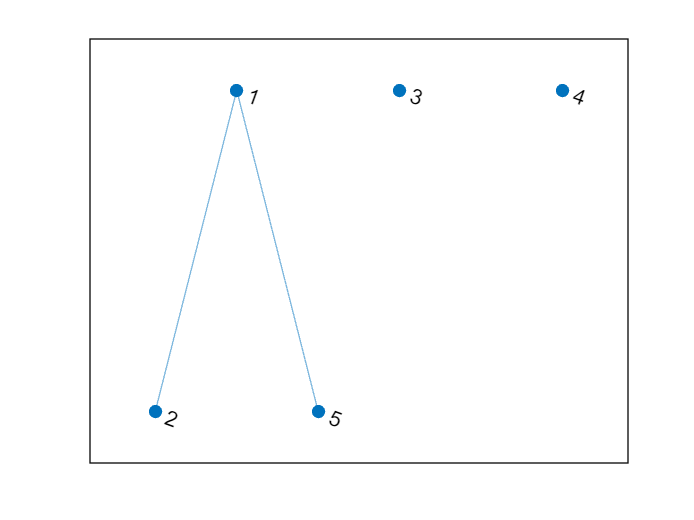


arista = [3, 5];

res = perteneceCiclo(A, arista);


disp(res);

   0



function res = perteneceCiclo(A, arista)

    [fil, col] = size(A);
    % La matriz de adyacencia debe ser cuadrada y simétrica
    if ~(fil == col ...
        && isequal(A, A'))
        disp('Error: Matriz de adyacencia no válida');
        res = false;
        return
    end

    % La arista debe tener dos componentes enteras distintas que toman valores entre 1 y el número de nodos
    if ~(length(arista) == 2 ...
        && all(arista == round(arista)) ...
        && arista(1) ~= arista(2) ...
        && all(arista >= 1 & arista <= fil))
        disp('Error: Arista no válida');
        res = false;
        return
    end
    
    % Se elimina la arista que queremos comprobar
    A(arista, flip(arista)) = 0;
    
    % Se recorrerá el grafo empezando por el nodo determinado por la primera componente de la arista
    vistos = zeros(1, fil);
    vistos(arista(1)) = 1;

    % La arista pertenece a un ciclo si se puede ir de uno de sus extremos al otro tras eliminarla del grafo inicial 
    res = dfs(A, arista(1), arista(2), vistos);
end

function res = dfs(grafo, actual, objetivo, vistos)
    vecinos = grafo(actual, :);
    vecinos_no_visitados = find(vecinos - (vecinos & vistos));
    figure
    plot(graph(grafo))

    for i = 1:length(vecinos_no_visitados)
        vistos(vecinos_no_visitados(i)) = 1;
        if ismember(objetivo, vistos)
            res = true;
            break
        end
        if vecinos_no_visitados(i) == objetivo
            break
        end
        arista = [actual, vecinos_no_visitados(i)];
        grafo(arista, flip(arista)) = 0;
        dfs(grafo, vecinos_no_visitados(i), objetivo, vistos);
        res = false;
    end
end